% This script generate verification prediction using both models and
% produce ROC curve of both models
% the dataset used to test is LFW dataset

clear all;
close all;

## load essentials

addpath(fullfile("Models/TemplateMatching")); % load TemplateMatching
addpath(fullfile("Models/VGGFace"));          % load VGGFace
addpath(genpath("Common"));                   % load common functions

datasetPath = fullfile("FaceDatabase/lfw-funneled-scaled-224");
embeddedDatasetPath = fullfile("FaceDatabase/lfw-funneled-scaled-224-embedded");
pairDetailPath = fullfile("Common/lfw-details/pairs.txt");

modelParamsPath = fullfile("Weights/VGGFace/VGGFaceParams.mat");

## Verfication using Template Matching (zero norm cross correlation of 2 images)

% read pairs defined in LFW dataset
pairsTable = readLFWPairsTxt(pairDetailPath);

imds = imageDatastore(datasetPath, "IncludeSubfolders",true,"LabelSource","foldernames");

% generate pair indices and true labels with batch size of infinite (defined in
% function) to fit all data into one batch
[seqA, seqB, cellLabels, batchNum] = LFWPairBatchIndexer( imds, pairsTable, "batchSize", inf, "shuffle", false);

ccValue = [];

f = waitbar(0,'template matching verification');
for i = 1:length(seqA{:})
    tmp1= rgb2gray(readimage(imds, seqA{:}(i)));
    tmp1= double(tmp1(:))/255;
    tmp1=(tmp1-mean(tmp1))/std(tmp1); 
    
    tmp2= rgb2gray(readimage(imds, seqB{:}(i)));
    tmp2= double(tmp2(:))/255;
    tmp2=(tmp2-mean(tmp2))/std(tmp2); 
    
    ccValue = [ccValue (tmp1'*tmp2)];
    waitbar(i/length(seqA{:}), f, 'template matching verification');
end
delete(f);

% max ccValue equals to higher correlation or higher similarity thus the
% postive class here is 1 to get the correct roc
% this is slightly different than distance measure where larger value
% represents lower similarity
[x4,y4,thres4,AUC4,optPoint4] = perfcurve(cellLabels{:}, ccValue, 1);

## Verfication using VGGFace

%% LOAD MODEL
model = VGGFace_LoadModel(modelParamsPath);
    
% target size for the network
targetSize = model.Layers(1,1).InputSize;

VGGFace_ExternalPrecompute(datasetPath, embeddedDatasetPath, 64);

% read pairs defined in LFW dataset
pairsTable = readLFWPairsTxt(pairDetailPath);

% load them as datastore
fds = fileDatastore( ...
        embeddedDatasetPath, ...
        'ReadFcn',@(x) cell2mat(struct2cell(load(x))), ...
        "IncludeSubfolders",true, ...
        "FileExtensions",'.mat' ...
        );

% load everything (embedding is very small compare to images)
embeddings = readall(fds);
embeddings = cat(4, embeddings{:}); % concat cell arrays of embeddings into 4d matrix

% generate pair indices and true labels with batch size of infinite (defined in
% function) to fit all data into one batch
[seqA, seqB, cellLabels, batchNum] = LFWPairBatchIndexer( fds, pairsTable, "batchSize", inf, "shuffle", false);

% calculate distances
% distance measures are inverted where higher values represent lower
% similarity thus the postive class here is inverted to get the correct roc
result_eul2 = VGGFace_Verify(model, embeddings(:,:,:,seqA{:}), embeddings(:,:,:,seqB{:}), [1 1], "euclidean_l2");
result_eu = VGGFace_Verify(model, embeddings(:,:,:,seqA{:}), embeddings(:,:,:,seqB{:}), [1 1], "euclidean");
result_cos = VGGFace_Verify(model, embeddings(:,:,:,seqA{:}), embeddings(:,:,:,seqB{:}), [1 1], "cosine");

[x1,y1,thres1,AUC1,optPoint1] = perfcurve(cellLabels{:}, -[result_eul2.distance], 1);
[x2,y2,thres2,AUC2,optPoint2] = perfcurve(cellLabels{:}, -[result_eu.distance], 1);
[x3,y3,thres3,AUC3,optPoint3] = perfcurve(cellLabels{:}, -[result_cos.distance], 1);

## Plot ROC

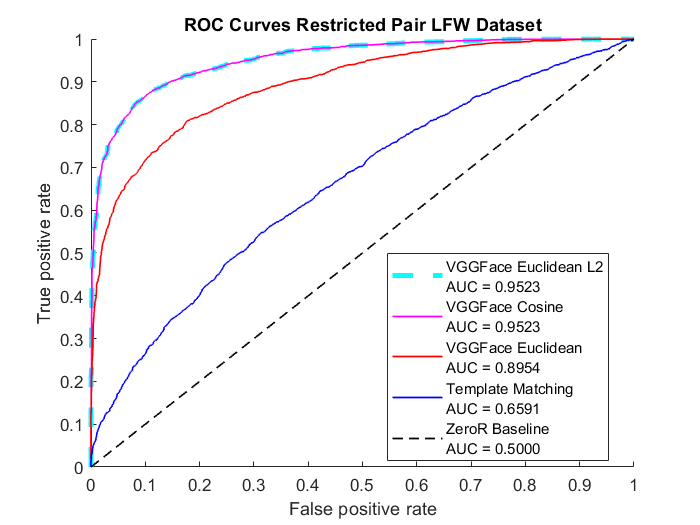

figure
hold on
p = plot(x1,y1, '--c');
p.LineWidth = 3;
p = plot(x3,y3, '-m');
p.LineWidth = 1;
p = plot(x2,y2, '-r');
p.LineWidth = 1;
p = plot(x4,y4, '-b');
p.LineWidth = 1;
p = plot(x1,x1, '--k');
p.LineWidth = 1;
legend( ...
    sprintf('VGGFace Euclidean L2\nAUC = %.4f',AUC1), ...
    sprintf('VGGFace Cosine\nAUC = %.4f',AUC3), ...
    sprintf('VGGFace Euclidean\nAUC = %.4f',AUC2), ...
    sprintf('Template Matching\nAUC = %.4f',AUC4), ...
    sprintf('ZeroR Baseline\nAUC = 0.5000'), ...
    "Location", "best")
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curves Restricted Pair LFW Dataset')
hold off